# Manivela

clear

EjeManivela=readtable("MatLab cinetica\Reacciones manivela\Eje-manivela-Der.txt","Delimiter"," ");

EjeManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

EjeManivela = 160×9 table
       T         Fz        Fy         Fx         F           Mz          My        Mx          M     
    _______    ______    _______    _______    ______    __________    ______    ______    __________

          0     836.9    -771.25    -324.91    1.3029    1.5472e+05    4971.3    -11180    1.5423e+05
    0.00402    890.22    -820.39     -345.6    1.3859    1.6458e+05    5287.9    -11893    1.6406e+05
    0.00803    943.62    -869.63    -366.28     1.469    1.7445e+05    5604.3    -12606    1.7391e+05
    0.01205     997.1    -918.98     -386.9    1.5523    1.8436e+05    5919.9    -13322    1.8378e+05
    0.01606    1050.6    -968.44    -407.38    1.6357  


BielaManivela=readtable("MatLab cinetica\Reacciones manivela\Biela-manivela-Der.txt","Delimiter"," ");

BielaManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

BielaManivela = 160×9 table
       T         Fz         Fy        Fx        F       Mz     My      Mx      M  
    _______    _______    ______    ______    ______    __    _____    __    _____

          0    -771.09    1.3029    324.89    836.74    0     5e-05    0     5e-05
    0.00402    -820.22    1.3859    345.57    890.05    0         0    0         0
    0.00803    -869.45     1.469    366.25    943.44    0         0    0         0
    0.01205    -918.79    1.5523    386.87    996.92    0         0    0         0
    0.01606    -968.26    1.6357    407.35    1050.5    0         0    0         0
    0.02008    -1017.9    1.7192    427.65    1104.1    0         0    0         0
 


D_manivela=0.08

D_manivela = 0.0800

d_eje=0.06

d_eje = 0.0600

b_manivela=0.02

b_manivela = 0.0200

h_manivela=D_manivela

h_manivela = 0.0800

W=0.018;
H=0.011;
L=b_manivela;

%4140 T=205
Sut=1470  

Sut = 1470

Sy=1360

Sy = 1360

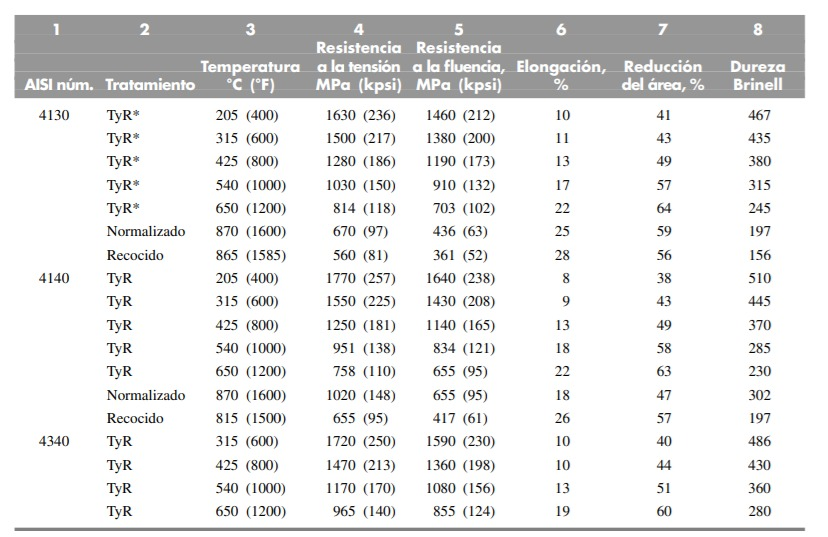

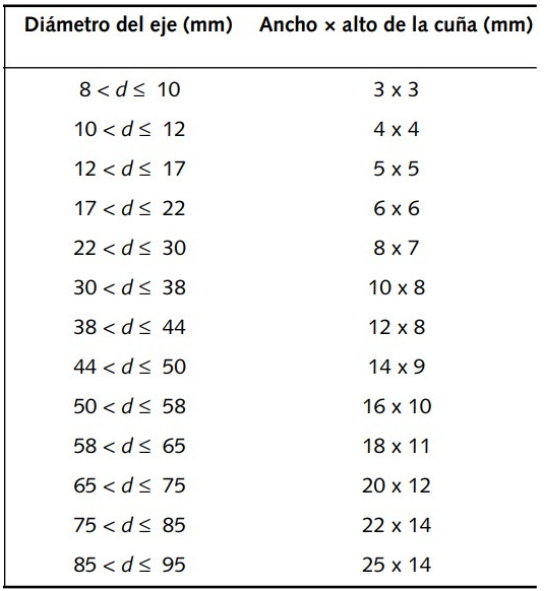



vectorTiempo=BielaManivela.T;
ExtremoEjeFy=-EjeManivela.Fx;
ExtremoEjeFz=EjeManivela.Fz;
ExtremoEjeFx=EjeManivela.Fy;
EjeTorqueMz=EjeManivela.Mz/1000;
EjeTorqueMx=EjeManivela.My/1000;
EjeTorqueMy=-EjeManivela.Mx/1000;
ExtremoBielaFy=BielaManivela.Fz;
ExtremoBielaFz=-BielaManivela.Fy;
ExtremoBielaFx=BielaManivela.Fx;



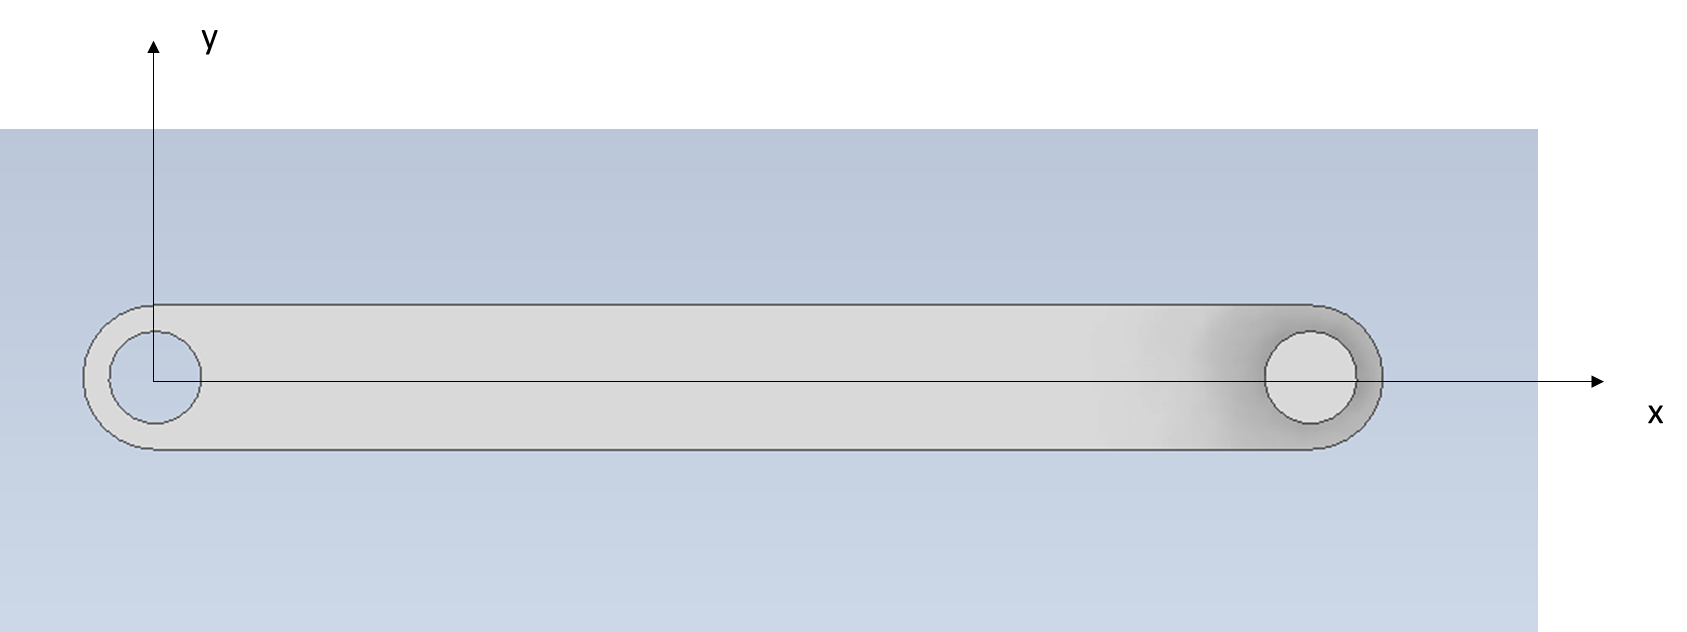

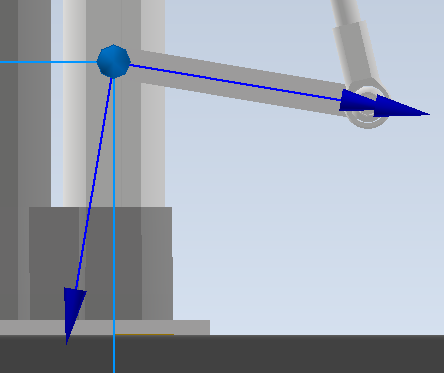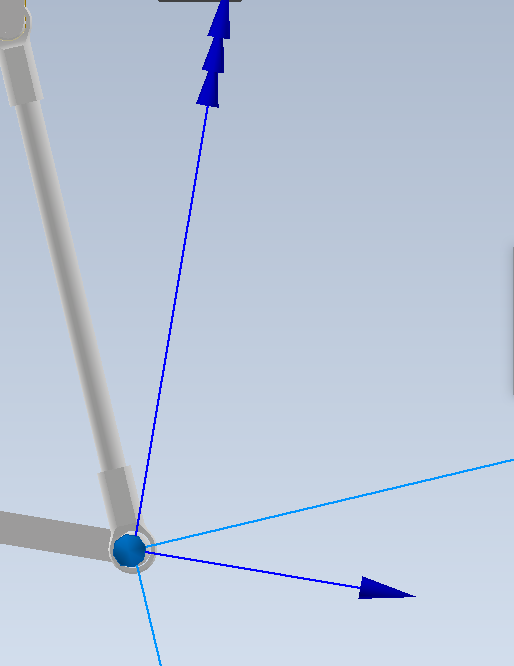

difFx=ExtremoBielaFx+ExtremoEjeFx;
difFy=ExtremoBielaFy+ExtremoEjeFy;
difFz=ExtremoEjeFz+ExtremoBielaFz;


## Análisis unión biela-manivela

ExtremoBielaFy

ExtremoBielaFz

ExtremoBielaFx

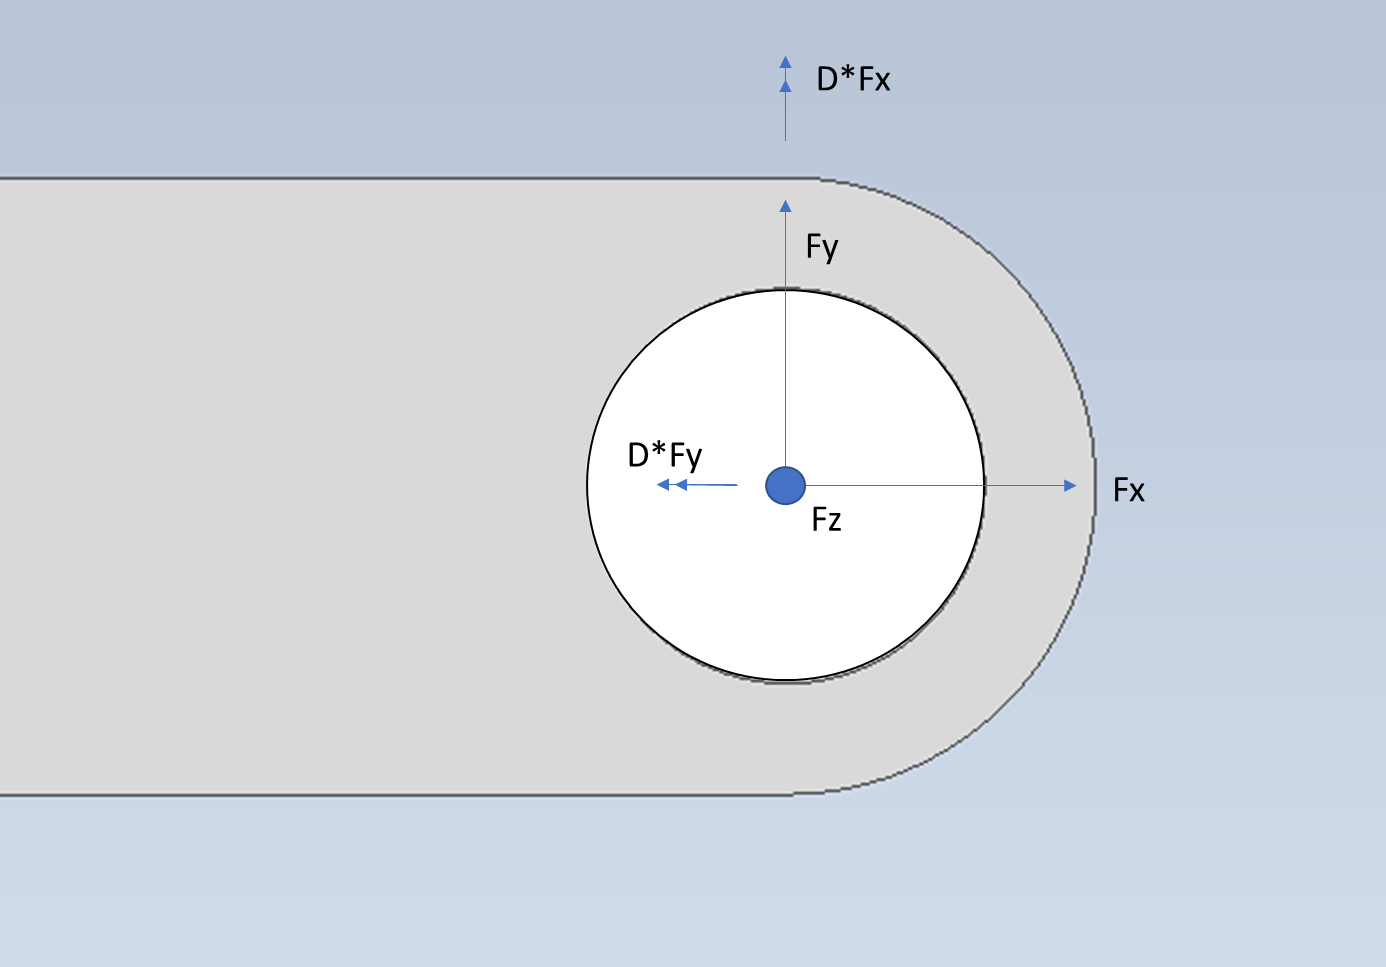

h_bm=0.0125;
D_bm=0.016;
I=pi*D_bm^4/64;
A=pi*D_bm^2/4;
My=h_bm*ExtremoBielaFx;
Mx=h_bm*ExtremoBielaFy;
MT=sqrt(My.^2+Mx.^2);

Sigma_t=MT*0.5*D_bm/I;
Sigma_c=-MT*0.5*D_bm/I;
Sigma_normal=ExtremoBielaFz/A;

Sigma_t_Total=(Sigma_normal+Sigma_t);
Sigma_c_Total=(Sigma_normal+Sigma_c);


### Fatiga

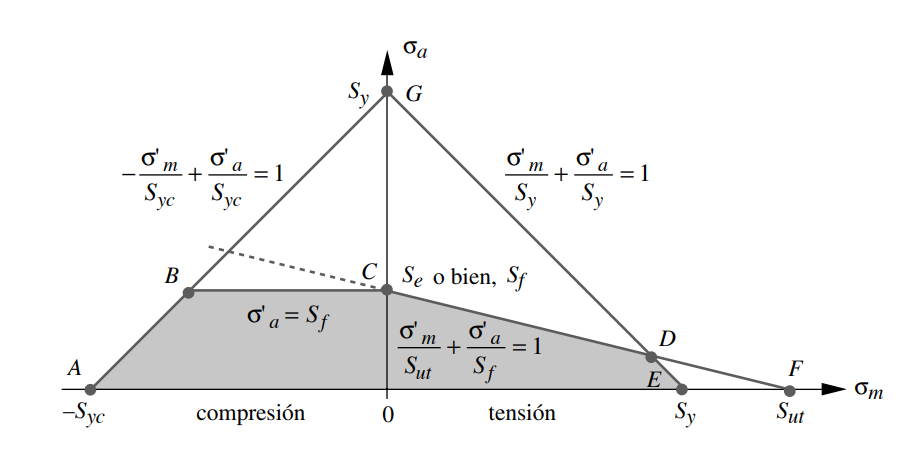

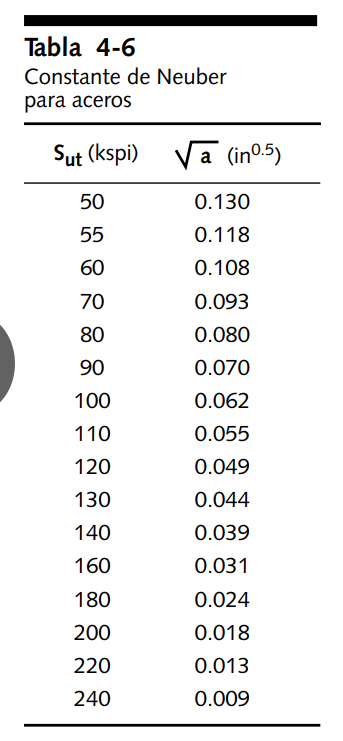

kt=2

kt = 2

neuberF=0.009 %Corregir neuber

neuberF = 0.0090

neuberT=0.005

neuberT = 0.0050

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1)

KfSold = 1.9723

KfsmSold=1+qTorsion*(kt-1)

KfsmSold = 1.9844

KtSoldadura=2

KtSoldadura = 2

mega=1000000;
sigmaA=KfSold*0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega   %esfuerzo alternante

sigmaA = 26.0357

sigmaM=KfSold*0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega   %esfuerzo medio

sigmaM = 51.4169

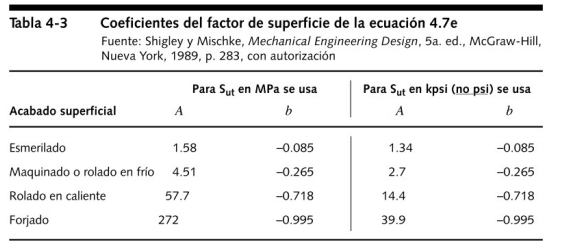

#### Factores de corrección


Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;

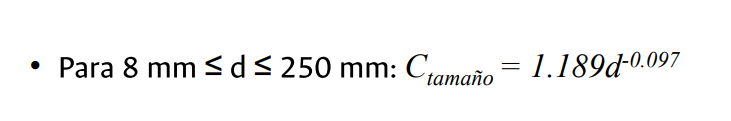

Ctam=1.189*(D_bm*1000)^(-0.097);
Ccon=0.897;
if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end

Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 366.8861

#### Diagrama de Goodman modificado

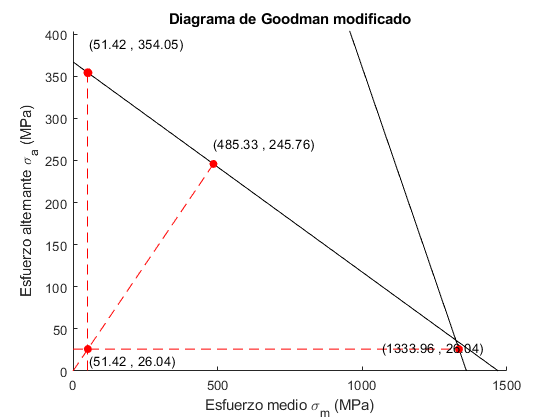

FS1 = 13.5988

FS2 = 9.4392

FS3 = 25.9441

FS_union_biela = 9.4392

FS_union_biela=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis unión eje-manivela


A_seccion=b_manivela*(D_manivela-d_eje)

A_seccion = 4.0000e-04

J=pi/32*(D_manivela^2-d_eje^2)

J = 2.7489e-04

I=pi/64*(D_manivela^2-d_eje^2)

I = 1.3744e-04

r_externo=0.5*D_manivela

r_externo = 0.0400


Kt=1.8

Kt = 1.8000


%NPI kts

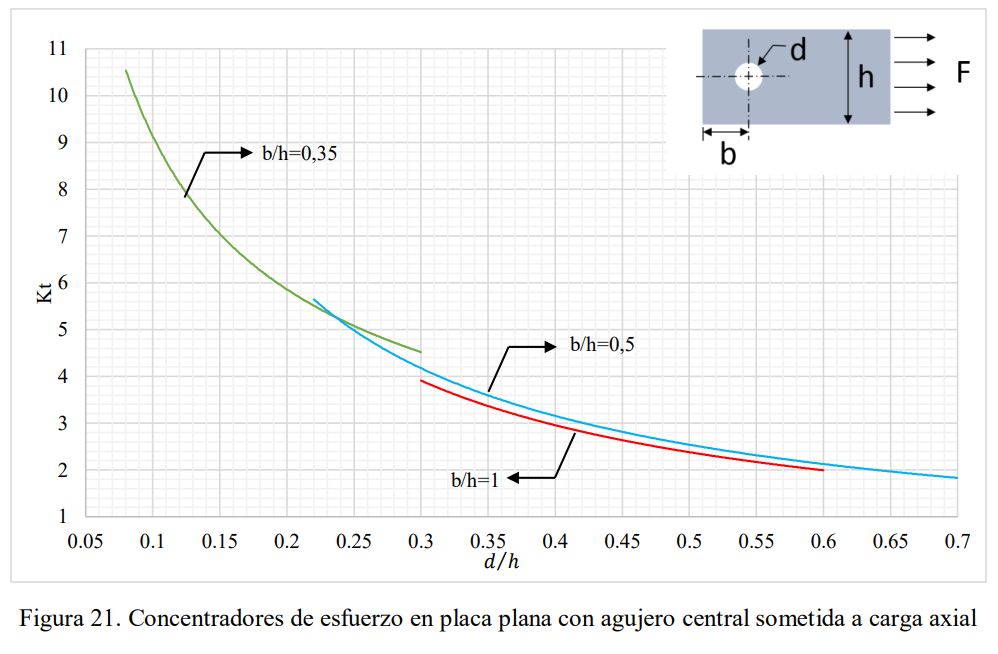

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1)

Kf = 1.9723

Kfsm=1+qTorsion*(kt-1)

Kfsm = 1.9844





Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/I; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*r_externo/I; %Momento flector: +z->i,-z->-i


tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r_externo/J; %Momento cortante:  +y->+k,-y->-k


Sigma_total=Sigma_Fx+Sigma_Mz+sigma_My;
tau_total=sqrt(tau_Vy.^2+(tau_Vz+tau_Mx).^2);


Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total))

Sigma_Alternante = 1.0121e+06

Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total))

Sigma_Medio = -2.0684e+06

Tau_Alternante=0.5*(max(tau_total)-min(tau_total))

Tau_Alternante = 1.1740e+06

Tau_Medio=0.5*(max(tau_total)+min(tau_total))

Tau_Medio = 2.2102e+06


sigmaA=sqrt((Kf*Sigma_Alternante).^2+3*(Kfsm*Tau_Alternante).^2)/mega

sigmaA = 4.5020

sigmaM=sqrt((Kf*Sigma_Medio).^2+3*(Kfsm*Tau_Medio).^2)/mega

sigmaM = 8.6230

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5;
d_eq=sqrt(A_95/0.0766);

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9388


Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 265.3469

#### Diagrama de Goodman

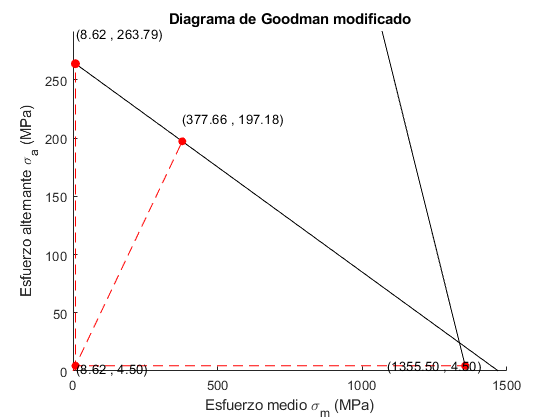

FS1 = 58.5936

FS2 = 43.7971

FS3 = 157.1962

FS_cortante_eje = 43.7971

FS_cortante_eje=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero Cortante

%parametros cuña


A_t=W*L;

r_eje=0.5*d_eje;
Torque=EjeTorqueMz;
r_cuna=0.03*d_eje;

k_t=1.9

k_t = 1.9000

k_ts=2.75

k_ts = 2.7500


k_f=1+qFlexion*(k_t-1)

k_f = 1.8751

k_fs=1+qTorsion*(k_ts-1)

k_fs = 2.7228


Carga_cortante=Torque/r_eje;
tau_V=k_fs*Carga_cortante/A_t;

sigmaA=sqrt(3)*0.5*(max(tau_V)-min(tau_V))/mega

sigmaA = 34.7077

sigmaM=sqrt(3)*0.5*(max(tau_V)+min(tau_V))/mega

sigmaM = 70.9114

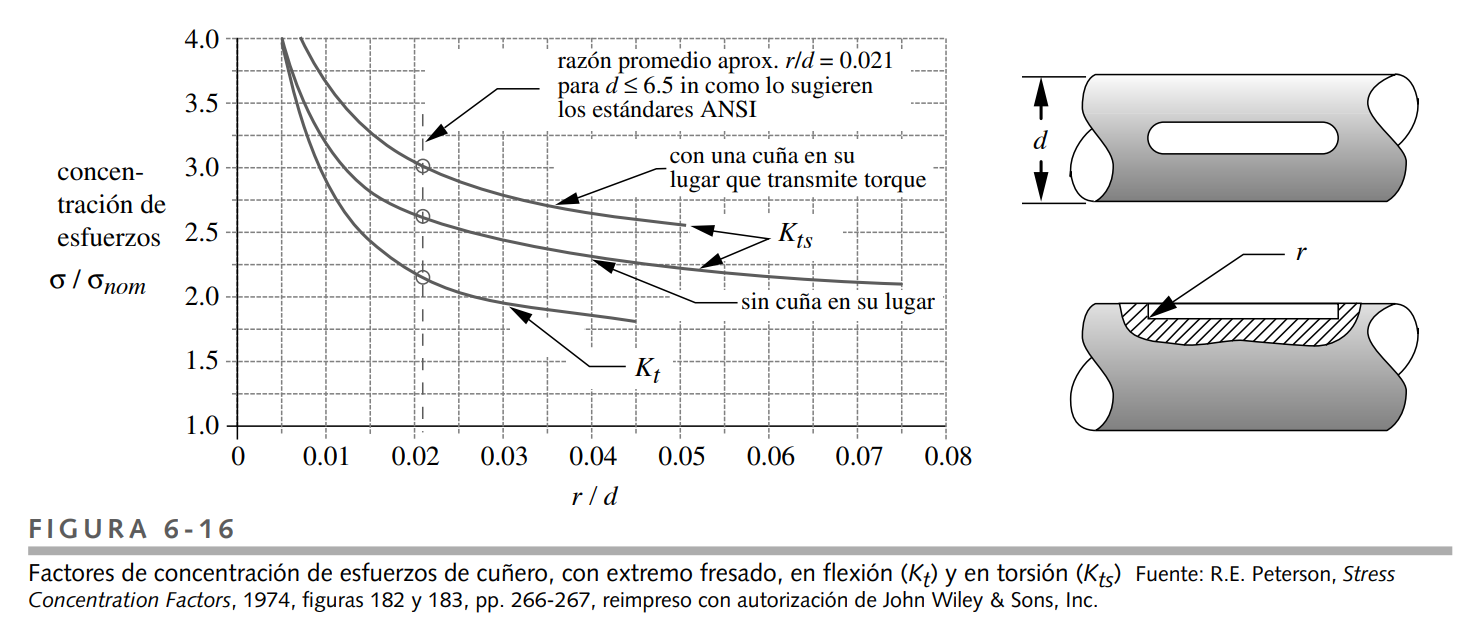

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05*L*W

A_95 = 1.8000e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0153

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9124


if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 368.4133

#### Diagrama de Goodman

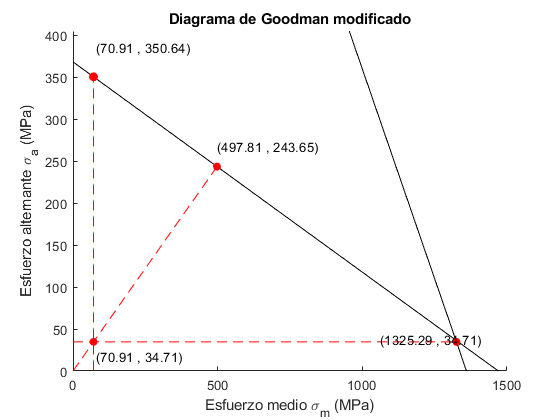

FS1 = 10.1027

FS2 = 7.0201

FS3 = 18.6894

FS_cortante_cuna = 7.0201

FS_cortante_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero aplastamiento


A_sigma=H*L;

sigma_V=k_fs*Carga_cortante/A_sigma;

sigmaA=0.5*(max(sigma_V)-min(sigma_V))/mega

sigmaA = 32.7903

sigmaM=0.5*(max(sigma_V)+min(sigma_V))/mega

sigmaM = 66.9939

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05* H*W

A_95 = 9.9000e-06

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0114

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9392



SeSC=0.5*Sut;
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 283.0049

#### Diagrama de Goodman

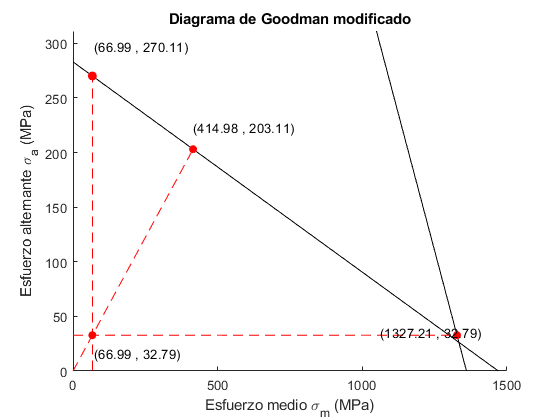

FS1 = 8.2374

FS2 = 6.1943

FS3 = 19.8109

FS_aplastamiento_cuna = 6.1943

FS_aplastamiento_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;


FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
%Fc2=Se==Sy+x3;
%Fr2=sigmaA.*x4/sigmaM==Se;

%lineaFN=@(x) Sy+x;
%FSn=double(solve(Fc2,x3));
%FSp=double(solve(Fr2,x4));
%fplot(lineaFN,[-Sy 0],"k")
%fplot(Se,[FSn 0],"k")
    

sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(8*sigmaM,2*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(8*sigmaM,1.1*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.1*FSm,1.1*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,2*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end